clc;
clear;
close all;

%joint limits
theta1_lim = linspace(-pi, pi, 36);
theta2_lim = linspace(-pi/2, pi/2, 12);
theta3_lim = linspace(-pi/2, pi/2, 12);
theta4_lim = linspace(-pi/2, pi/2, 12);

%link parameters
d1 = 0.2;
L1 = 0.5;
L2 = 0.5;
L3 = 0.2;

num_points = length(theta1_lim) * length(theta2_lim) * length(theta3_lim) * length(theta4_lim);
workspace_points = zeros(num_points, 3);
idx = 1;

%calculate positions iterate
for theta1 = theta1_lim
    for theta2 = theta2_lim
        for theta3 = theta3_lim
            for theta4 = theta4_lim

                x = cos(theta1)*(L1*cos(theta2+theta3)+L1*cos(theta2)-L3*sin(theta2+theta3+theta4));
                y = sin(theta1)*(L2*cos(theta2+theta3)+L1*cos(theta2)-L3*sin(theta2+theta3+theta4));
                z = d1+L2*sin(theta2+theta3)+L1*sin(theta2)+L3*cos(theta2+theta3+theta4);
                workspace_points(idx, :) = [x, y, z];
                idx = idx + 1;

            end
        end
    end
end

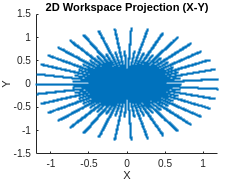


%2d projections
figure;
scatter(workspace_points(:,1), workspace_points(:,2), '.');
title('2D Workspace Projection (X-Y)');
xlabel('X'); ylabel('Y');

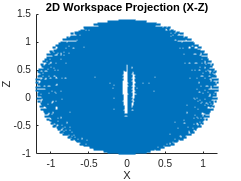


figure;
scatter(workspace_points(:,1), workspace_points(:,3), '.');
title('2D Workspace Projection (X-Z)');
xlabel('X'); ylabel('Z');

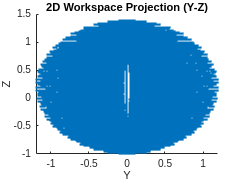


figure;
scatter(workspace_points(:,2), workspace_points(:,3), '.');
title('2D Workspace Projection (Y-Z)');
xlabel('Y'); ylabel('Z');

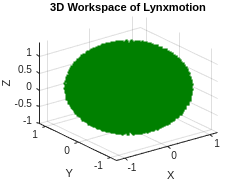

%3d workspace
figure;
scatter3(workspace_points(:,1), workspace_points(:,2), workspace_points(:,3), '.', 'MarkerEdgeColor', [0, 0.5, 0]);
title('3D Workspace of Lynxmotion');
xlabel('X'); ylabel('Y'); zlabel('Z');
filename = 'workspace.png';
exportgraphics(gcf, filename, 'ContentType', 'vector');